# Ejercicio 1. Wavelets 

#### **Detección de cambios con wavelets.**

Las señales con una rápida evolución, como la respuesta en el régimen transitorio de los sistemas dinámicos, pueden presentar cambios abruptos en la señal o en su primera o segunda derivada (cambio de curvatura). Un análisis basado en Fourier no es capaz de detectar estos cambios. Sin embargo, un análisis basado en wavelets nos permite detectar el instante exacto en que la señal cambia.

#### Tarea propuesta:

Identificación del instante en que cambia la curvatura en una señal.

**a)** Carga la señal contenida en “signal.mat” y represéntala en el dominio del tiempo discreto.

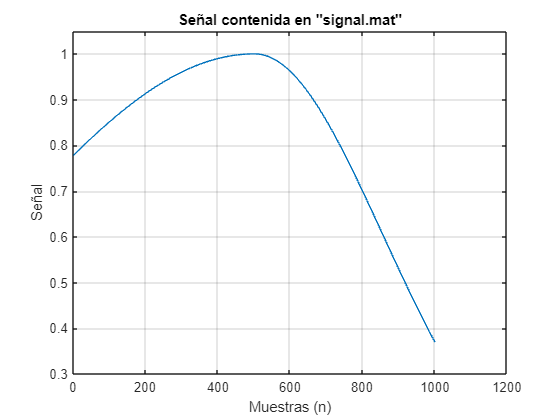

load('signal.mat')
plot(signal)
ylim([0.3 1.05])
ylabel('Señal')
xlabel('Muestras (n)')
title('Señal contenida en "signal.mat"');
grid;

`En la figura aparece un cambio en la curvatura se la señal, aproximadamente puede estimarse que para un valor de muestra entre 400 y 600. Para hacer un primer estudio veamos como se observará un cambio de este tipo en el histograma de la señal.`

**b)** Representa el espectrograma de la señal e identifica el instante en qué se produce el cambio de curvatura si es posible.

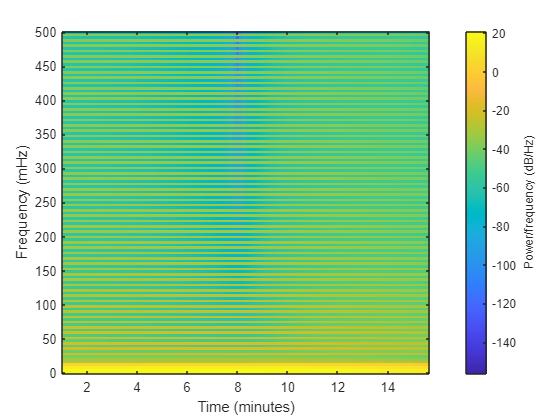

figure()
spectrogram(signal,128,120,[],1);
view(90,-90);

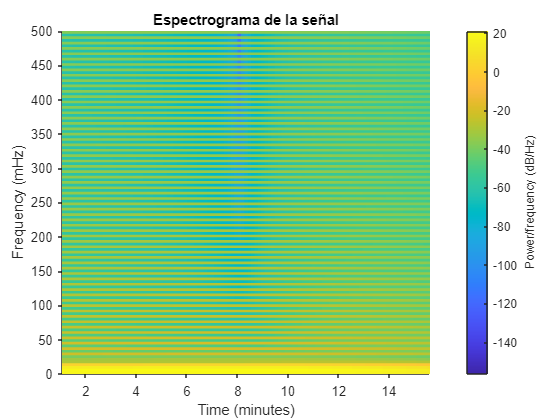

title('Espectrograma de la señal')

`Un hisotrama no es capaz de dar mucha más información que la simple representación temporal. Observando la figura se llega a intuir un cambio en las componentes frecuenciales de la señal a los 8 minutos de su comienzo aproximadamente. Este punto coincide con el momento en que se observaba un cambio en el dominio temporal. El historama simplemente sirve para discretizar en que rangos de valores temporales aparecen cambios, pero de una manera muy imprecisa. Este diagrama ha permitido conocer que tansolo aparece un cambio significativo en todo el dominio temporal.`

**c)** Representa la función wavelet, ψ, Daubechies 4 y su función de escalado, φ, correspondiente. Nota: El comando “wavefun” de Matlab devuelve la función wavelet y la función de escalado de un determinado tipo, que hay que indicar como parámetro de entrada. Para indicar el tipo Daubechies 4 emplea ‘db4’.

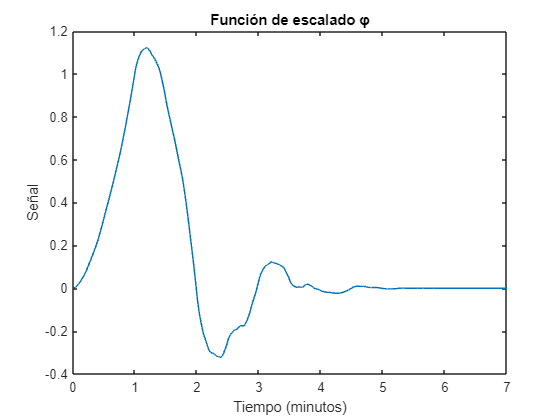

[phi,psi,t] = wavefun('db4');
figure()
plot(t,phi)
ylabel('Señal')
xlabel('Tiempo (minutos)')
title('Función de escalado φ');

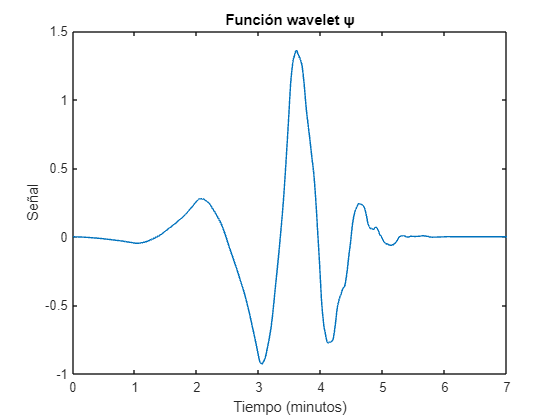

figure()
plot(t,psi)
ylabel('Señal')
xlabel('Tiempo (minutos)')
title('Función wavelet ψ');

**d)** Representa los coeficientes de detalle de nivel 1 de forma que sea posible detectar el cambio en la señal. Nota1: emplea el comando de Matlab “wavedec” para obtener la descomposición basada en wavelets, el comando “detcoef” para extraer los coeficientes de detalle de un nivel concreto, y el comando “dyadup” para realizar el padding que permita la comparación de los coeficientes anteriores con la onda original. Nota 2: el inicio y el final de la señal también serán detectados como cambios. Para que esa información no dificulte la detección del cambio buscado, evita la representación de los coeficientes de los extremos.

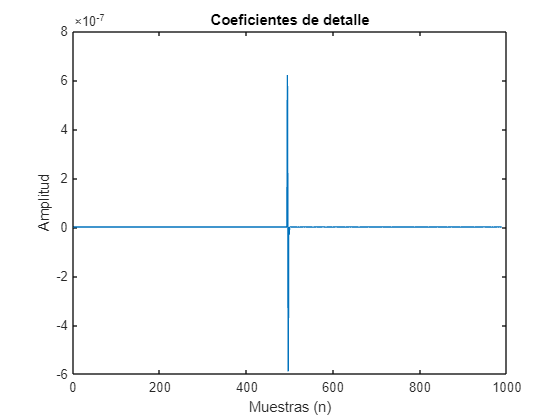

level=1;
[c,l] = wavedec(signal,level,'db4');
[d0] = detcoef(c,l,level);
dlup = dyadup(d0,0);
dlup = dlup(10:(length(dlup)-10));
figure()
plot(dlup)
ylabel('Amplitud')
xlabel('Muestras (n)')
title('Coeficientes de detalle');

`Los coeficientes de detalle dan cuenta de los cambios que sufre una señal a lo largo del tiempo. Cuanto mayor es el numero de coeficientes de detalle que se calculan mayor será el nivel de infomación que se tendrá acerca de la señal descompuesta. Los coeficientes de detalle con un bajo nivel escala (según la terminología de MatLab) representan las frecuencias más altas de la señal. Estos coeficientes de detalle son mayores en los instantes en que aparecen cambios abruptos. A medida que el nivel de escala aumenta los coeficientes de detalle tendrán componentes mayores para frecuencias más bajas. `

`En este caso truncamos el desarollo al primer nivel de escala. La información restante estará contenida en los coeficientes de aproximación, que dan cuenta de los valores promedio de la señal en cada intervalo.`

`Como este coeficiente de detalle tiene relevancia tansolo para las frecuencias más altas observamos un pico muy marcado con su máximo localizado para la muestra número 494. Esto permite saber con exactitud en que punto se ha producido el cambio que buscabamos.`